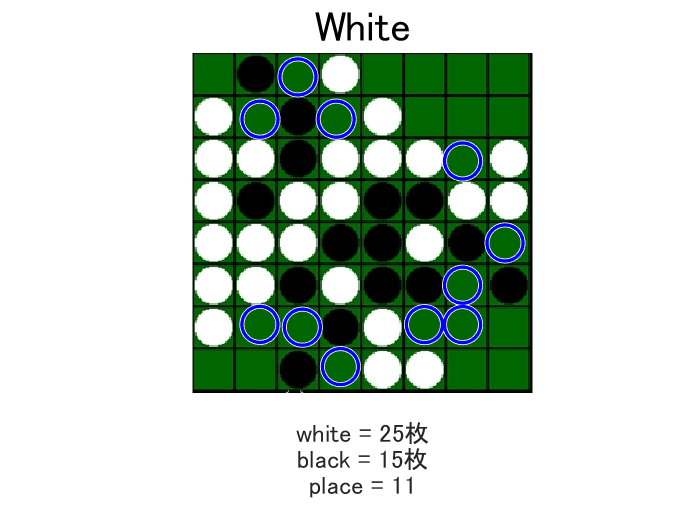

clear
% オセロ認識 
I=imread('オセロ4.png');

main(I,0,'b');

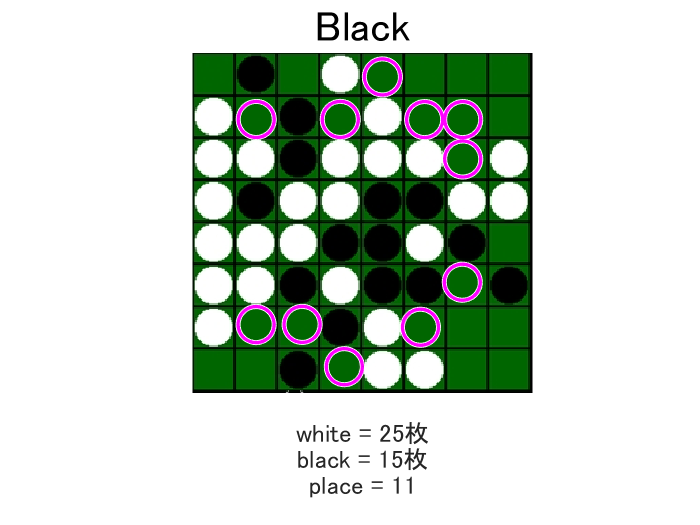

%viscircles(centnewB, radnewB,'Color','b');

main(I,1,'m');

%viscircles(centnewD, radnewD,'Color','m');

% 探索する関数。
% i_plus と j_plus に 0, 1, -1 を入れることで探索する方向を決める。

function [tf,i_ans,j_ans]=check_search(A,i,j,i_plus,j_plus,judge)
tf=false;
i_ans=0;
j_ans=0;
if A(i,j)==100 && (A(i+i_plus,j+j_plus)==abs(judge-1) || A(i-i_plus,j-j_plus)==abs(judge-1))
    if A(i-i_plus,j-j_plus)==100 || A(i-i_plus,j-j_plus)==2 || A(i-i_plus,j-j_plus)==3  % 右側にだけコマが置かれていたら
        [tf,i_ans,j_ans]=serach(A,i,j,i_plus,j_plus,judge);  % 左右方向の探索
    elseif A(i+i_plus,j+j_plus)==100 || A(i+i_plus,j+j_plus)==2 || A(i+i_plus,j+j_plus)==3  % 左側にだけ駒が置かれていたら
        [tf,i_ans,j_ans]=serach(A,i,j,-i_plus,-j_plus,judge);
    else
        [tf,i_ans,j_ans]=serach(A,i,j,i_plus,j_plus,judge);  % 左上から右下にかけての斜め方向の探索
        if tf==false
            [tf,i_ans,j_ans]=serach(A,i,j,-i_plus,-j_plus,judge);  % 左下から右上にかけての斜め方向の探索
        end
    end
end

% 探索する関数。i_plus と j_plus に 0, 1, -1 を入れることで探索する方向を決める。
function [tf,i_ans,j_ans]=serach(A,i,j,i_plus,j_plus,judge)
tf=false;
count=0;
i_ans=0;
j_ans=0;
while j>1 || j<10 
    count=count+1;
    if A(i+i_plus,j+j_plus)==2 || A(i+i_plus,j+j_plus)==100 || A(i+i_plus,j+j_plus)==3 || tf==true
        break
    elseif A(i+i_plus,j+j_plus)==judge
        tf=true;
    end
    % 右側と左側どちらにも石があった場合、右側から探索しているため探索基準のすぐ右側が探索したい色だった場合、
    % 正しく探索できないので、tf=false にして break で抜け、すぐに左側の探索に移る。
    if count==1 && tf==true
        tf=false;
        break
    end
    % 置ける場所を探索後、元の座標に戻す際、置ける場所の隣にある石の中心座標を基準に
    % 次置ける場所の中心座標を求めるため、どちらの方向に石があるのかを把握するための処理。
    if count==1
        i_ans=i_plus;
        j_ans=j_plus;
    end
    i=i+i_plus;
    j=j+j_plus;
end
end
end

% メイン関数。これを呼び出すだけで次に置ける場所などの情報をすべて出力できる。
function V=main(I,judge,color)
figure; imshow(I,"InitialMagnification",'fit')
R=(max(size(I))-18)/8;  % 枠線分の大きさ(18)を引いている。
Rmax = floor(R/2);
Rmin = floor(R/4);
[centB, radB] = imfindcircles(I,[Rmin Rmax],'ObjectPolarity','bright');
[centD, radD] = imfindcircles(I,[Rmin Rmax],'ObjectPolarity','dark','EdgeThreshold',0.1);
centBD=[centB; centD];

% 現在の白黒を10×10の配列で表現する。
% 外枠の分も含めるため8×8ではなく10×10である。
A=ones(10)+1;
A(2:9,2:9)=A(2:9,2:9)+98;
aa=round(centB/R);
bb=round(centD/R);
cc=[aa;bb];
for i=1:length(aa)
    a=aa(i,:)+1;  % 外枠分、ずれているため +1
    A(a(2),a(1))=0;
end
for i=1:length(bb)
    b=bb(i,:)+1;  % 外枠分、ずれているため +1
    A(b(2),b(1))=1;
end
% 探索
% どの色がどこに置けるのかを探索する判定するための変数。0=白, 1=黒
cent=zeros(64,2);
count=1;
for i=2:9
    for j=2:9
        [tf_row,i_ans_row,j_ans_row]=check_search(A,i,j,0,1,judge);  % 横方向に置けるかの探索。tf_row=true なら置ける。
        [tf_col,i_ans_col,j_ans_col]=check_search(A,i,j,1,0,judge);  % 縦方向に置けるかの探索。tf_col=true なら置ける。
        [tf_dd,i_ans_dd,j_ans_dd]=check_search(A,i,j,1,1,judge);  % 左上から右下方向にかけて斜めに置けるかの探索。tf_dd=true なら置ける。
        [tf_du,i_ans_du,j_ans_du]=check_search(A,i,j,1,-1,judge);  % 左下から右上方向にかけて斜めに置けるかの探索。tf_du=true なら置ける。
        % 横方向の探索
        if tf_row==true
            A(i,j)=3;
            [~, Locb] = ismember([j+j_ans_row-1 i+i_ans_row-1],cc, 'rows');
            cent(count,:)=[centBD(Locb(1),1)-(R-1)*j_ans_row centBD(Locb(1),2)-R*i_ans_row];
            count=count+1;
        end        
        % 縦方向の探索
        if tf_col==true
            A(i,j)=3;
            [~, Locb] = ismember([j+j_ans_col-1 i+i_ans_col-1],cc, 'rows');
            cent(count,:)=[centBD(Locb(1),1)-(R-1)*j_ans_col centBD(Locb(1),2)-R*i_ans_col];
            count=count+1;
        end
        % 左上から右下にかけての斜め方向の探索
        if tf_dd==true
            A(i,j)=3;            
            [~, Locb] = ismember([j+j_ans_dd-1 i+i_ans_dd-1],cc, 'rows');
            cent(count,:)=[centBD(Locb(1),1)-(R-1)*j_ans_dd centBD(Locb(1),2)-R*i_ans_dd];
            count=count+1;
        end
        % 左下から右上にかけての斜め方向の探索
        if tf_du==true
            A(i,j)=3;
            [~, Locb] = ismember([j+j_ans_du-1 i+i_ans_du-1],cc, 'rows');
            cent(count,:)=[centBD(Locb(1),1)-(R-1)*j_ans_du centBD(Locb(1),2)-R*i_ans_du];
            count=count+1;
        end
    end
end

% 縦横斜めで、置ける場所が被ってしまった場合、すべて出力すると重なってしまい見にくい上に
% 置ける場所を数える際に正確な値を求められないため、重複をなくす。
len=length(find(cent))/2;
for i=1:len-1
    for j=i+1:len
        if cent(j,1)>=cent(i,1)-5 && cent(j,1)<=cent(i,1)+5 && cent(j,2)>=cent(i,2)-5 && cent(j,2)<=cent(i,2)+5
            cent(j,:)=0;
        end
    end
end
% 要素が [0 0] の行を削除する。
idx = cent(:,1)==0 & cent(:,2)==0;
centnew=cent(~idx,:);

% 置ける場所の中心座標と同じ長さで出ないと出力できないので、
% 同じ長さの列ベクトルを作成する。
radnew=zeros(numel(centnew)/2,1);
radDmax=min(radD);
radBmax=min(radB);
radmax=min(radDmax, radBmax);
radnew=radnew+radmax;

% 白(0) ならタイトルを 'White' にし、黒(1) ならタイトルを 'Black' にする。
if judge==0
    title('White','FontSize',25);
elseif judge==1
    title('Black','FontSize',25);
end
S=sprintf('white = %d枚\nblack = %d枚\nplace = %d\n',length(centB),length(centD),numel(centnew)/2); 
xlabel(S,'FontSize',15)

V=viscircles(centnew, radnew,'Color',color);
end